%% Coupled transport aircraft sizing and longitudinal CG
% Standalone MATLAB script. All inputs are specified below.
% Fixed installed thrust and fixed wing area define the design point at each mass.
% Fuel is the original full-tank load; crew and payload are added once.
clear; clc;
% Script-defined inputs take precedence over the parameter record.
AR = 10;
W0 = 267609;           % Initial take-off mass [kg]
e_oswald = 0.70;
CD0 = 0.0186;
M_cruise = 0.82;
L_runway = 3000;       % m
abs_ceil_ft = 42000;
V_climb = 150;         % m/s
gamma_req = 0.024;
g          = 9.81;
ft2m       = 0.3048;
sigma_to   = 1.0;      % density ratio for sea level
K_R        = 1.0;      % runway correction factor
Sa         = 305;      % air distance safety margin [m]
CLmax_L    = 2.55;      % landing CL_max (slide 23).
CLmax_TO   = 2.33;      % take-off CL_max
CL_LOF     = 0.8*CLmax_TO;
NE         = 2;        % number of engines
alpha_to   = 1.0;      % take-off weight ratio
taxiMassRatio = 0.99;                       
fuelFraction_TO = (0.35296 - (1 - taxiMassRatio)) / taxiMassRatio;
alpha_cr = (0.97 * 0.985) / taxiMassRatio;  % cruise weight ratio (0.97*0.985)
alpha_ceil = alpha_cr*0.712;   % weight ratio at absolute ceiling
beta_cr    = 0.23;     % thrust lapse, cruise (slide 12)
beta_30k   = 0.30;     % thrust lapse, 30,000 ft line
beta_40k   = 0.20;     % thrust lapse, 40,000 ft line
beta_ceil  = 0.20;     % thrust lapse, absolute ceiling
installedThrust_N = 2 * 392.5e3;  % Total installed take-off thrust [N], both engines
S_ref_out = 422.199;                % Fixed wing reference area [m^2]
b_out = sqrt(AR*S_ref_out);
areaScale = S_ref_out/422.199;

K_induced  = 1/(pi*AR*e_oswald);   % induced drag factor

%% ------------------------------------------------------------------------
%% 2. WING LOADING GRID AND LIMITS
%% ------------------------------------------------------------------------
N_WS = 8000;
WS   = linspace(500, 9000, N_WS);  % wing loading [N/m^2]

ALD_max         = 0.60*L_runway;
WS_landing_limit = (ALD_max - Sa)*sigma_to*CLmax_L/(0.51*K_R);   % check vs slide

%% ------------------------------------------------------------------------
%% 3. CONSTRAINT CURVES (T/W against W/S)
%% ------------------------------------------------------------------------
% Take-off (Raymer take-off parameter)
TOP_req    = L_runway/(0.297 - 0.019*NE);
TW_takeoff = (WS/(sigma_to*CL_LOF*TOP_req))/alpha_to;

% OEI climb (constant in W/S)
TW_climb2     = (gamma_req + 2*sqrt(CD0*K_induced)) / 0.5;
TW_climb2_vec = TW_climb2*ones(size(WS));

% AEO Go-Around (constant in W/S)
TW_climb3     = (gamma_req + 2*sqrt(0.11*K_induced));
TW_climb3_vec = TW_climb3*ones(size(WS));

% Absolute ceiling: V_x evaluated at ceiling density (updated in the solver below)
h_ceil_m       = abs_ceil_ft*ft2m;
[~, ~, ~, rho_ceil] = atmosisa(h_ceil_m);

% at cruise altitude

% Cruise lines
TW_30k = cruiseTW(WS, 30000, beta_30k, alpha_cr, M_cruise, CD0, K_induced, ft2m);
TW_37k = cruiseTW(WS, 37000, beta_cr,  alpha_cr, M_cruise, CD0, K_induced, ft2m);
TW_40k = cruiseTW(WS, 40000, beta_40k, alpha_cr, M_cruise, CD0, K_induced, ft2m);

% Climb lines
TW_c10_3000 = climbTW(WS, 1000, 3000, V_climb, 0.85,    alpha_cr, CD0, K_induced, ft2m);
TW_c10_1500 = climbTW(WS, 10000, 1500, V_climb, 0.85,    alpha_cr, CD0, K_induced, ft2m);
[~, a_cruise, ~, ~] = atmosisa(37000*ft2m);
V_c37k      = M_cruise*a_cruise;                              % estimated TAS at 37,000 ft
TW_c37k     = climbTW(WS, 37000,  500, V_c37k, beta_cr,  alpha_cr, CD0, K_induced, ft2m);
b_max = 65;
% Calculate separately at EVERY wing loading.

V_ceil = sqrt(2*alpha_ceil*WS/rho_ceil) .* (K_induced/CD0)^(1/4);

q_ceil = 0.5*rho_ceil .* V_ceil.^2;

TW_ceil = (alpha_ceil/beta_ceil) .* (q_ceil.*CD0./(alpha_ceil*WS) + K_induced.*(alpha_ceil*WS)./q_ceil);

% Envelope: required T/W is the maximum of all constraints
% Include AEO go-around, which was omitted previously.

TW_env = max([TW_takeoff;
              TW_ceil;
              TW_climb2_vec;
              TW_climb3_vec;
              TW_30k;
              TW_37k;
              TW_40k;
              TW_c10_3000;
              TW_c10_1500;
              TW_c37k], [], 1);
%% Iterate mass with fixed geometry and installed thrust
KG2LB = 2.20462;
LB2T = 1000*KG2LB;
massTolerance_kg = 0.1;
maxIterations = 100;
for iteration = 1:maxIterations
    ws = W0*g/S_ref_out;
    TW_design = installedThrust_N/(W0*g);
    fprintf('Iteration %d: mass %.2f kg, W/S %.2f N/m^2, T/W %.5f\n', ...
            iteration, W0, ws, TW_design);
    % ------------------------------------------------------------------------
    %  VARIABLES - input!!!!
    x_ac_w = 27.32;                        % Original wing station, m from nose
    x_root_ht = 51.3785;  % HT root leading edge, m aft of nose
    x_root_vt = 53.03;    % VT root leading edge, m aft of nose
    % ------------------------------------------------------------------------

    % --- Crew / payload --- [confirmed]
    n_pilots = 3;                       % Flight crew on all four loading cases
    n_cabin_crew = 5;                   % Cabin crew on passenger cases
    N_c = n_pilots + n_cabin_crew;       % Staffed passenger configuration
    N_seat_E    = 90;                       % Economy seats [confirmed]
    N_seat_PE   = 36;                       % Premium economy seats [confirmed]
    N_seat_B    = 24;                       % Business seats [confirmed]
    N_pax       = N_seat_E + N_seat_PE + N_seat_B;   % Passengers (150) [confirmed]
    N_p         = N_pax + N_c;              % Total persons onboard (crew + passengers) [confirmed]

    % --- Geometry: wing --- [confirmed]

    Bw          = 3.281*b_out;              % Wing span (ft) [variable]
    Sw          = 3.281^2*S_ref_out;           % Reference wing area (ft^2) [variable]
    Scsw        = 3.281^2*47.44*areaScale;            % Area of wing mounted control surfaces (ft^2) [variable]
    lambda      = 0.2325;                    % Wing taper ratio [confirmed]
    Lambda_w    = 32.42;                    % Wing quarter chord sweep (deg) [confirmed]
    tc_root     = 0.14;                     % (t/c)_root, wing root thickness to chord ratio [confirmed]

    % --- Geometry: horizontal tail --- [confirmed]
    S_ref_A_m2 = S_ref_out; %[confirmed]
    c_root_A_m   = 2*S_ref_out/(b_out*(1+lambda));        % Wing root chord [m]
    MAC_A_m      = (2/3) * c_root_A_m * (1 + lambda + lambda^2) / (1 + lambda);
    S_e         = 23.75/ft2m^2;                % Elevator area (ft^2) [variable]
    AR_h = 4;
    tr_h = 0.4;
    Lambda_ht = 36;  % Quarter-chord sweep [deg]
    Ht_Hv = 0;  % Fuselage-mounted HT
    [S_ht_m2, x_ac_ht] = sizeTail(S_ref_A_m2*MAC_A_m, x_root_ht, x_ac_w, ...
        AR_h, tr_h, Lambda_ht, 0.5);
    tail_arm_A_m = x_ac_ht - x_ac_w;
    L_ht = 3.281*tail_arm_A_m;
    S_ht = 3.281^2*S_ht_m2;
    B_t         = sqrt(AR_h*S_ht);                 % Horizontal tailplane span (ft) [confirmed]
    c_root_h = 2*S_ht / (B_t*(1 + tr_h));
    c_tip_h  = tr_h * c_root_h;
    MAC_h = (2/3) * c_root_h * (1 + tr_h + tr_h^2) / (1 + tr_h);

    % --- Geometry: vertical tail --- [confirmed]
    span_A_m = b_out;
    AR_v = 1.7;
    tr_v = 0.35;
    Lambda_vt = 40;  % Quarter-chord sweep [deg]
    [S_vt_m2, x_ac_vt] = sizeTail(0.09*S_ref_A_m2*span_A_m, x_root_vt, x_ac_w, ...
        AR_v, tr_v, Lambda_vt, 1);
    tail_arm_vt_m = x_ac_vt - x_ac_w;
    L_vt = 3.281*tail_arm_vt_m;
    S_vt = 3.281^2*S_vt_m2;
    tc_root_v   = 0.11;                     % (t/c)_root_v, vertical tail root thickness to chord ratio [variable]
    b_v =  sqrt(AR_v*S_vt); % Vertical tail height [ft]
    c_root_v = 2*S_vt / (b_v*(1 + tr_v));
    c_tip_v  = tr_v * c_root_v;
    MAC_v = (2/3) * c_root_v * (1 + tr_v + tr_v^2) / (1 + tr_v);

    % --- Geometry: fuselage / nacelle --- [confirmed]
    D           = 3.281*5.8047;              % Maximum fuselage diameter (ft)[confirmed]
    x_tail_tip_m   = 62.988;                    % Tail-tip station from nose [m]
    tail_taper_m   = 11.6095;                   % Length of tapered afterbody [m]
    x_tail_start_m = x_tail_tip_m - tail_taper_m;
    D_tail_start_m = 5.8047;                    % Diameter at start of taper [m]
    D_tail_tip_m   = 1.08;                      % Diameter at tail tip [m]
    x95_m = x_tail_start_m + 0.95*tail_taper_m;  % 95% along tapered afterbody
    D_local = @(x) interp1([x_tail_start_m, x95_m, x_tail_tip_m], ...
                           [D_tail_start_m, 1.161, D_tail_tip_m], x, 'linear');
    F_w = 3.281*D_local(x_root_ht);  % Local diameter at centre-mounted HT root [ft]
    assert(isfinite(F_w) && isfinite(D_local(x_root_vt)), 'Tail roots outside afterbody.');
    L_f         = 3.281*x_tail_tip_m;              % Total fuselage length (ft) [confirmed]
    x_tailcap_joint_m = 0.517;                % Tail-cap structural joint location (m) [confirmed]
    x_radome_joint_m  = 1.795;                % Radome structural joint location (m) [confirmed]
    L           = 3.281*(L_f/3.281- x_tailcap_joint_m - x_radome_joint_m);  % Fuselage structural length (ft) [confirmed]
    S_f         = 3.281^2*1006.1;             % Fuselage wetted area (ft^2) [confirmed]
    N_Lt        =  6.56 / 0.3048;                     % Nacelle length (ft) [confirmed]
    N_w         = 3.34 / 0.3048;                    % Nacelle width (ft) [confirmed]
    S_n         =  60.0 / 0.3048^2;                     % Nacelle wetted area (ft^2) [confirmed]
    V_pr        = 3.281^3*1048.2;         % Volume of pressurized sections (ft^3) [confirmed]

    % --- Propulsion --- [unconfirmed]
    N_en        = 2;                        % Number of engines [confirmed] 
    x_engine = x_ac_w/0.3048 - 0.5*N_Lt;  % Existing engine CG estimate [ft]
    y_pylon = mean([11.37, 11.87]) / 0.3048;
    L_ec        = 2*(x_engine + y_pylon);                      % Engine controls routing distance, engine to cockpit (ft) [unconfirmed]

    % --- Fuel system --- [confirmed]
    W_dg        = KG2LB*W0;             % Design gross weight (lb) [confirmed]
    W_fuel      = W_dg *fuelFraction_TO; %0.35296; %weight of the fuel [lbs]
    V_t         =  (W_fuel/ KG2LB / 775) * 264.172;
    % Design mission fuel (lb);[confirmed]
    V_i         = V_t;                      % Integral fuel tank volume (gal) [confirmed]
    V_p         = 0;                        % Self sealing tank volume (gal) [confirmed]
    N_t         = 3;                        % Total number of fuel tanks [confirmed]

    % --- Weights --- [confirmed]
    W_l         = W_dg - W_fuel*0.7;       % Landing design gross weight (lb), 70% of loaded fuel consumed
    W_en        = KG2LB*7265;               % Engine weight (lb) [confirmed]
    W_APU       = 762;                      % Uninstalled APU weight (lb) [confirmed]
    W_c         = KG2LB*(40000 + N_seat_B*35 + N_seat_PE*28 + N_seat_E*23);  % Max cargo + pax bags (lb) [confirmed]
    TW0         = TW_design;                    % Thrust-to-weight ratio T/W0 (input) [variable]
    W_uav       = 0.02*(W_dg*(0.32 + 0.66*W_dg^(-0.13)*AR^0.30*TW0^0.06*(W_dg/Sw)^(-0.05)*M_cruise^0.05)*1.0);  % Uninstalled avionics, 0.02 x W_empty (Raymer Table 6.1, jet transport, K_vs = 1.0); (0.02-0.04 from raymer) [confirmed]
    W_seat_E    = 35*KG2LB;                 % Weight of single economy seat (lb)
    W_seat_PE   = 80*KG2LB;                 % Weight of single premium economy seat (lb)
    W_seat_B    = 175*KG2LB;                % Weight of single business class seat (lb)
    N_LD3 = 62;
    W_ULD_lb = N_LD3 * 74 * KG2LB;
    % --- Load factors --- [confirmed]
    N_z         = 1.5*2.5;                  % Ultimate load factor = 1.5 x limit load factor
    N_gear      = 3;                      % Ratio of avg total main gear load on landing to max landing weight
    N_l         = 1.5*N_gear;               % Ultimate landing gear load factor

    % --- Landing gear --
    % Gear lengths for weight equations (in)
    L_m         = 39.3701*5;              % Main landing gear length (in) [guess]
    L_n         = 39.3701*5;              % Nose landing gear length (in) [guess]
    N_mw        = 12;                       % Number of main wheels [confirmed]
    N_nw        = 2;                        % Number of nose wheels [confirmed]
    N_mss       = 2;                        % Number of main gear shock struts
    V_stall_TO_mps = 65.48;  % Recorded take-off stall speed [m/s]
    V_stall_L_mps = 49.82;   % Landing stall speed [m/s]

    % --- Controls / systems ---
    N_f         = 7;                        % Number of functions performed by controls; typ. 4-7 [[confirmed]]
    N_m         = 0;                        % Number of mechanical functions performed by controls; typ. 0-2 [confirmed]
    S_cs        = (20.63+26.39+23.75+20.39)/ft2m^2;                    % Total control surface area (ft^2) [unconfirmed]
    R_kva       = 400;                      % System electrical rating; typ. 40-60 for transports (kVA) [confirmed]
    L_a         = L_ec;                 % Electrical routing distance, generators to avionics to cockpit (ft) [unconfirmed]
    N_gen       = 4;                        % Number of generators; typ. = N_en (+1?) [confirmed]

    % --- Empirical K factors (defaults = 1.0 "otherwise" case) --- [confirmed]
    K_buf       = 5.68;   % 1.02 short ranges; 5.68 very long ranges [confirmed]
    K_door      = 1.18;    % 1.0 no cargo door; 1.06 one side door; 1.12 two side doors or aft clamshell; 1.25 two side + aft clamshell [confirmed] 1.18=1+0.06*3
    K_lav       = 1.11;   % 1.11 long range; 0.31 short range; 3.9 business jets [confirmed]
    K_Lg        = 1.0;    % 1.12 fuselage mounted landing gear; 1.0 otherwise [confirmed]
    K_mp        = 1.0;    % 1.126 kneeling main gear; 1.0 otherwise [confirmed]
    K_ng        = 1.017;    % 1.017 pylon mounted nacelle; 1.0 otherwise [confirmed]
    K_np        = 1.0;    % 1.15 kneeling nose gear; 1.0 otherwise [confirmed]
    K_r         = 1.0;    % 1.133 reciprocating engines; 1.0 otherwise [confirmed]
    K_tp        = 1.0;    % 0.793 turboprop; 1.0 otherwise [confirmed]
    K_uht       = 1.0;    % 1.143 all-moving tail; 1.0 otherwise [confirmed]
    K_p         = 1.0;    % 1.4 engine with propeller; 1.0 otherwise [confirmed] 
    K_tr        = 1.18;    % 1.18 jet with thrust reversers; 1.0 otherwise [confirmed]

    % --- Derived quantities from the nomenclature ---
    K_ws        = 0.75*((1 + 2*lambda)/(1 + lambda))*Bw*tand(Lambda_w)/L;  % Wing sweep factor
    K_y         = 0.3*L_ht;                 % Pitching radius of gyration (ft)
    K_z         = L_vt;                     % Yaw radius of gyration (ft)
    I_y         = W_dg*K_y^2;               % Pitching moment of inertia (lb ft^2), W_o ~ W_dg
    W_enc       = 2.331*K_p*K_tr*W_en^0.901;  % Weight of engine and contents (lb)

    % --- Material factors (composite fudge factors, from Raymer) --- [confirmed]
    MF_w  = 0.78;   % wing
    MF_tp = 0.75;   % tail planes
    MF_F  = 0.85;   % fuselage / nacelle
    MF_lg = 0.88;   % landing gear

    % ------------------------------------------------------------------------
    %  WEIGHT EQUATIONS
    % ------------------------------------------------------------------------

    % Wing
    W_w = (0.0051*(W_dg*N_z)^0.557*Sw^0.649*AR^0.5*(1 + lambda)^0.1*Scsw^0.1) ...
          ./(cosd(Lambda_w)*tc_root^0.4);
    W_w = MF_w*W_w;

    % Horizontal tail
    W_ht = (0.0379*K_uht*W_dg^0.639*N_z^0.1*S_ht^0.75*K_y^0.704*AR_h^0.166 ...
           *(1 + S_e/S_ht)^0.1) ...
           ./((1 + F_w/B_t)^0.25*L_ht*cosd(Lambda_ht));
    W_ht = MF_tp*W_ht;

    % Vertical tail
    W_vt = (0.0026*(1 + Ht_Hv)^0.225*W_dg^0.556*N_z^0.536*S_vt^0.5*K_z^0.875*AR_v^0.35) ...
           ./(L_vt^0.5*cosd(Lambda_vt)*tc_root_v^0.5);
    W_vt = MF_tp*W_vt;

    % Fuselage
    W_fus = 0.3280*K_door*K_Lg*(W_dg*N_z)^0.5*L^0.25*S_f^0.302*(1 + K_ws)^0.04*(L/D)^0.1;
    W_fus = MF_F*W_fus;

    % Main landing gear 
    W_main_landing_gear = 0.0106*K_mp*W_l^0.888*N_l^0.25*L_m^0.4*N_mw^0.321*(V_stall_L_mps/0.514444)^0.1/N_mss^0.5;
    W_main_landing_gear = MF_lg*W_main_landing_gear;

    % Nose landing gear
    W_nose_landing_gear = 0.032*K_np*W_l^0.646*N_l^0.2*L_n^0.5*N_nw^0.45;
    W_nose_landing_gear = MF_lg*W_nose_landing_gear;

    % Nacelle
    W_nacelle = 0.6724*K_ng*N_Lt^0.1*N_w^0.294*N_z^0.119*W_enc^0.611*N_en^0.984*S_n^0.224;
    W_nacelle = MF_F*W_nacelle;

    % Engines
    W_engines = N_en*W_en;

    % Engine controls
    W_ec = 5*N_en + 0.8*L_ec;

    % Engine (pneumatic) starter
    W_es = 49.19*(N_en*W_en/1e3)^0.541;

    % Fuel system
    W_fuel_system = 2.405*V_t^0.606*N_t^0.5*(1 + V_p/V_t)/(1 + V_i/V_t);

    % Flight controls
    W_flight_controls = 145.9*N_f^0.554*S_cs^0.2*(I_y*1e-6)^0.07/(1 + N_m/N_f);

    % Installed APU
    W_APUinst = 2.2*W_APU;

    % Instruments
    W_instruments = 4.509*K_r*K_tp*N_c^0.541*N_en*(L_f + Bw)^0.5;

    % Hydraulic system
    W_hydraulic = 0.2673*N_f*(L_f + Bw)^0.937;

    % Electrical system
    W_electrical = 7.291*R_kva^0.782*L_a^0.346*N_gen^0.1;

    % Avionics
    W_avionics = 1.73*W_uav^0.983;

    % Furnishings
    W_furnishings = 0.0577*N_c^0.1*W_c^0.393*S_f^0.75...
    + N_seat_E*W_seat_E + N_seat_PE*W_seat_PE + N_seat_B*W_seat_B ...
        + K_lav*N_p^1.33 + K_buf*N_p^1.12+W_ULD_lb;

    % Air-conditioning
    W_ac = 62.36*N_p^0.25*(V_pr*1e-3)^0.604*W_uav^0.1;

    % Anti-icing system
    W_anti_icing = 0.002*W_dg;

    % Handling gear (civilian)
    W_hg = 3.0e-4*W_dg;

    % ------------------------------------------------------------------------
    %  SUMMARY
    % ------------------------------------------------------------------------
    names   = {'Wing','Horizontal tail','Vertical tail','Fuselage','Main landing gear', ...
               'Nose landing gear','Nacelle','Engines','Engine controls','Engine starter','Fuel system', ...
               'Flight controls','Installed APU','Instruments','Hydraulics','Electrical', ...
               'Avionics','Furnishings','Air-conditioning','Anti-icing','Handling gear'};
    weights = [W_w W_ht W_vt W_fus W_main_landing_gear W_nose_landing_gear W_nacelle W_engines W_ec W_es W_fuel_system W_flight_controls W_APUinst ...
               W_instruments W_hydraulic W_electrical W_avionics W_furnishings W_ac W_anti_icing W_hg];

    payloadCrew_lb = [N_pax*84*KG2LB, W_c, N_c*84*KG2LB];
    cg_weights = [weights, W_fuel, payloadCrew_lb];
    builtMass_kg = sum(cg_weights)/KG2LB;
    validateattributes(builtMass_kg, {'numeric'}, {'scalar','real','finite','positive'});
    residual_kg = builtMass_kg - W0;
    if abs(residual_kg) <= massTolerance_kg
        break
    end
    if iteration == maxIterations
        error('MTOW failed to close after %d iterations. Residual %+.3f kg.', iteration, residual_kg);
    end
    W0 = builtMass_kg;
end

Iteration 1: mass 267609.00 kg, W/S 6218.03 N/m^2, T/W 0.29902
Iteration 2: mass 258693.02 kg, W/S 6010.86 N/m^2, T/W 0.30933
Iteration 3: mass 254206.02 kg, W/S 5906.60 N/m^2, T/W 0.31479
Iteration 4: mass 251942.03 kg, W/S 5854.00 N/m^2, T/W 0.31761
Iteration 5: mass 250798.15 kg, W/S 5827.42 N/m^2, T/W 0.31906
Iteration 6: mass 250219.80 kg, W/S 5813.98 N/m^2, T/W 0.31980
Iteration 7: mass 249927.29 kg, W/S 5807.18 N/m^2, T/W 0.32017
Iteration 8: mass 249779.31 kg, W/S 5803.74 N/m^2, T/W 0.32036
Iteration 9: mass 249704.45 kg, W/S 5802.00 N/m^2, T/W 0.32046
Iteration 10: mass 249666.58 kg, W/S 5801.12 N/m^2, T/W 0.32051
Iteration 11: mass 249647.41 kg, W/S 5800.68 N/m^2, T/W 0.32053
Iteration 12: mass 249637.72 kg, W/S 5800.45 N/m^2, T/W 0.32055
Iteration 13: mass 249632.81 kg, W/S 5800.34 N/m^2, T/W 0.32055
Iteration 14: mass 249630.33 kg, W/S 5800.28 N/m^2, T/W 0.32056
Iteration 15: mass 249629.08 kg, W/S 5800.25 N/m^2, T/W 0.32056
Iteration 16: mass 249628.44 kg, W/S 5800.24 N/m^

WS_span_min = W0*g*AR/b_max^2;
fprintf('\nMTOW %.3f kg, component sum including load %.3f kg, residual %+.4f kg (%d iterations).\n', ...
    W0, builtMass_kg, residual_kg, iteration);


MTOW 249627.956 kg, component sum including load 249627.873 kg, residual -0.0823 kg (18 iterations).


TW_required = interp1(WS,TW_env,ws,'linear');
V_x_out = sqrt(2*alpha_ceil*ws/rho_ceil)*(K_induced/CD0)^(1/4);
if ~isfinite(TW_required)
    warning('Converged W/S lies outside the plotted performance grid.');
elseif TW_design < TW_required || ws > WS_landing_limit || b_out > b_max
    warning('Mass closed; the design violates a thrust, landing or span constraint.');
else
    fprintf('Converged point meets the modelled thrust, landing and span constraints.\n');
end

Converged point meets the modelled thrust, landing and span constraints.


% Print results
fprintf('\n--- SELECTED DESIGN POINT ---\n');


--- SELECTED DESIGN POINT ---


fprintf('Design W/S         = %.2f N/m^2\n', ws);

Design W/S         = 5800.23 N/m^2


fprintf('Selected T/W       = %.4f\n', TW_design);

Selected T/W       = 0.3206


fprintf('Minimum required TW= %.4f\n', TW_required);

Minimum required TW= 0.2910


fprintf('Wing area          = %.2f m^2\n', S_ref_out);

Wing area          = 422.20 m^2


fprintf('Wingspan           = %.2f m\n', b_out);

Wingspan           = 64.98 m


fprintf('Landing W/S limit  = %.2f N/m^2\n', ...
        WS_landing_limit);

Landing W/S limit  = 7475.00 N/m^2


weights_kg = weights/KG2LB;   % weight in kg

T = table(names', weights', weights_kg', 'VariableNames', {'Component','Weight_lb','weight_kg'});
disp(T);

          Component          Weight_lb    weight_kg
    _____________________    _________    _________

    {'Wing'             }      48495        21997  
    {'Horizontal tail'  }     4934.2       2238.1  
    {'Vertical tail'    }     4813.6       2183.4  
    {'Fuselage'         }      37834        17161  
    {'Main landing gear'}      27279        12373  
    {'Nose landing gear'}     3114.1       1412.5  
    {'Nacelle'          }     6032.2       2736.2  
    {'Engines'          }      32033        14530  
    {'Engine controls'  }     197.19       89.445  
    {'Engine starter'   }     320.93       145.57  
    {'Fuel system'      }     1064.5       482.86  
    {'Flight controls'  }     2608.8       1183.4  
    {'Installed APU'    }     1676.4        760.4  
    {'Instruments'      }     569.15       258.16  
    {'Hydraulics'       }     536.96       243.56  
    {'Electri

fprintf('Total of listed components: %.1f lb\n', sum(weights));

Total of listed components: 233603.1 lb


fprintf('Total of listed components: %.1f t\n', sum(weights)/LB2T);

Total of listed components: 106.0 t



% ------------------------------------------------------------------------
%  AXES
%  x: longitudinal distance from the nose, positive aft (m)
%  z: distance from fuselage centre, positive down (m)
%  y: distance from centreline, positive right (not used here)
% ------------------------------------------------------------------------

% ------------------------------------------------------------------------
%  LOCATION OF WEIGHTS FOR CG
% ------------------------------------------------------------------------
% Raymer approximate group method: wing/tails at 40% MAC,
% fuselage at 40-50% length; 45% selected here.
% System stations below are layout assumptions, not Raymer fixed fractions.

L_f_m   = L_f/3.281;
D_m     = D/3.281;
b_w_m   = Bw/3.281;
S_w_m   = Sw/3.281^2;
cr_w_m  = 2*S_w_m/(b_w_m*(1 + lambda));            % Trapezoidal wing assumption
MAC_w   = (2/3)*cr_w_m*(1 + lambda + lambda^2)/(1 + lambda);

lambda_ht_cg = tr_h;
lambda_vt_cg = tr_v;
b_ht_m  = B_t/3.281;
S_ht_m  = S_ht/3.281^2;
cr_ht_m = 2*S_ht_m/(b_ht_m*(1 + lambda_ht_cg));
MAC_ht  = (2/3)*cr_ht_m*(1 + lambda_ht_cg + lambda_ht_cg^2)/(1 + lambda_ht_cg);

S_vt_m  = S_vt/3.281^2;
b_vt_m  = sqrt(AR_v*S_vt_m);                       % Fin height (b^2 = AR*S)
cr_vt_m = 2*S_vt_m/(b_vt_m*(1 + lambda_vt_cg));
MAC_vt  = (2/3)*cr_vt_m*(1 + lambda_vt_cg + lambda_vt_cg^2)/(1 + lambda_vt_cg);


% Aerodynamic centres assumed at 25% MAC to locate MAC leading edges
x_LEMAC_w  = x_ac_w  - 0.25*MAC_w;
x_LEMAC_ht = x_ac_ht - 0.25*MAC_ht;
x_LEMAC_vt = x_ac_vt - 0.25*MAC_vt;

% % wing z position:
wing_root_chord_m = 10.5439;
wing_tip_chord_m  = 2.4515;
wing_span_m       = 64.9769;
% Wing-box placement includes the selected 1.5 m vertical offset; z positive down.
floor_top_z_m     = -0.2315;
floor_thickness_m = 0.05 * 5.5507;
wing_box_depth_m  = 0.14 * wing_root_chord_m;
z_w = floor_top_z_m + floor_thickness_m + 0.5*wing_box_depth_m + 1.5;%0.4*D =2.322
%%==================================================================
z_center = @(x) -(x - x_tail_start_m)*tand(12);
z_ht_base = z_center(x_root_ht);                        % HT root at local centre [m]
z_vt_base = z_center(x_root_vt) - 0.5*D_local(x_root_vt); % VT root at local crown [m]

x_engine_m   = x_engine*0.3048;             % Installation station [guess]
z_engine_m   = z_w + 0.5*N_w*0.3048;                 % Installation station [guess]

x_cockpit  = 5;                                    % Flight deck station [guess]
x_cabin    = 25.753+ 8.75                           % Combined cabin/crew station [guess]

x_cabin = 34.5030

x_equipment = 0.40*L_f_m;                          % Distributed systems station [guess]

% Component positions (m)
% Aircraft wings
c35 = 10.5439 + 0.35*(2.4515 - 10.5439);  % Local chord at 35% semispan [m]
xW_w = x_ac_w + (11.37096 - 12.87240)*tand(Lambda_w) + (0.43 - 0.25)*c35;
zW_w   = z_w;

% Horizontal tail: 38% semispan, 42% local chord
c38_ht = cr_ht_m * (1 - 0.38*(1 - lambda_ht_cg));
xW_ht = x_root_ht + 0.25*cr_ht_m + 0.38*(b_ht_m/2)*tand(Lambda_ht) + 0.17*c38_ht;
zW_ht = z_ht_base;  % Use tail-root mounting height if HT dihedral is neglected

% Vertical tail: trapezoidal centroid height, 40% MAC
h_vt = b_vt_m*(1 + 2*lambda_vt_cg)/(3*(1 + lambda_vt_cg));
xW_vt = x_root_vt + 0.25*cr_vt_m + h_vt*tand(Lambda_vt) + 0.15*MAC_vt;
zW_vt = z_vt_base - h_vt;  

% Fuselage
xW_fus = 0.45*L_f_m;               zW_fus = 0;
% Main landing gear (retracted): assumed near mid-chord of wing [guess]
xW_main_landing_gear = x_LEMAC_w + 0.50*MAC_w;   zW_main_landing_gear = z_w;
% Nose landing gear (retracted)
xW_nose_landing_gear = 6;                        zW_nose_landing_gear = 0.35*D_m;

% Nacelle
xW_nacelle = x_engine_m;                 zW_nacelle = z_engine_m;
% Engines
xW_engines = x_engine_m;             zW_engines = z_engine_m;
% Engine controls
xW_ec  = (x_cockpit + x_engine_m)/2; zW_ec  = z_w/2;
% Engine starter
xW_es  = x_engine_m;                 zW_es  = z_engine_m;

% Fuel system
xW_fuel_system = xW_w;                           % Fuel-system hardware [m]
zW_fuel_system = z_w;

% Flight controls
iamstupid= (-0.2315+D_m/2)/2;%-0.2315 is the floor uppersurface 
xW_flight_controls  = x_equipment;              zW_flight_controls  = 0;
% Installed APU
xW_APUinst = x95_m - 1.82/2;          zW_APUinst = z_center(xW_APUinst);
% Instruments
xW_instruments = x_cockpit;              zW_instruments = iamstupid;
% Hydraulics
xW_hydraulic = x_equipment;             zW_hydraulic =iamstupid;
% Electrical
xW_electrical   =  x_equipment;             zW_electrical   =  iamstupid;
% Avionics
xW_avionics   = x_equipment%1.795/2;           

xW_avionics = 25.1952

zW_avionics   = 0;
% Air-conditioning
xW_ac   = x_equipment;                  zW_ac   = iamstupid;
% Anti-icing
xW_anti_icing   = xW_w;                    zW_anti_icing   = z_w;

% Fuel, passengers, cargo, crew
m_fuel_kg   = W_fuel / KG2LB;
m_center_kg = 23.61 * 775;                       % m^3 * kg/m^3 = kg
m_wings_kg  = m_fuel_kg - m_center_kg;           % Both wings combined [kg]
y_MAC_m = (b_w_m/2)*(1 + 2*lambda)/(3*(1 + lambda));
x_LE_root_m = x_ac_w - y_MAC_m*tand(Lambda_w) - 0.25*wing_root_chord_m;
x_center_tank = x_LE_root_m + 0.35*wing_root_chord_m;
xW_Fuel = (m_center_kg*x_center_tank + m_wings_kg*xW_w) / m_fuel_kg;  zW_Fuel  = z_w;
x_cabin_start = 8.75;                          % m aft of nose
xW_Pass = x_cabin_start + 13.018816;      zW_Pass    =  -0.4565; % cabin z position

% Cargo zones: upper deck, lower deck forward of box, lower deck aft of box
wingbox_length = 11.86;
% Existing wing reference and cargo hold limits, all measured from the nose.
x_box_mid = x_ac_w + 0.25*MAC_A_m;
x_box_front = x_box_mid - wingbox_length/2;
x_box_aft = x_box_mid + wingbox_length/2;
n_rows_total = N_LD3/2;
n_rows_upper = 11;
n_lower = n_rows_total - n_rows_upper;
row_pitch_m = 1.53416;
[x_rows_forward,x_rows_aft] = arrangeLD3(x_cabin_start, L_f_m-10.041, ...
    x_box_front, x_box_aft, row_pitch_m, n_lower);

n_rows_forward = numel(x_rows_forward);
n_rows_aft = numel(x_rows_aft);
x_upper = x_cabin_start + 25.829 + 17.26/2;
xW_Cargo = (n_rows_upper*x_upper + sum(x_rows_forward) + sum(x_rows_aft))/n_rows_total;
zW_Cargo = (n_rows_upper*(-D_m/2 + 0.2315) + n_lower*(D_m/2 - 0.2315))/n_rows_total;
fprintf('Lower LD3 layout: %d forward rows, %d aft rows (2 containers per row).\n', ...
        n_rows_forward,n_rows_aft);

Lower LD3 layout: 9 forward rows, 11 aft rows (2 containers per row).


xW_crew  = (n_pilots*x_cockpit + n_cabin_crew*x_cabin)/N_c;  zW_crew =- 0.4565;

% Handling gear
xW_hg   = xW_Cargo;              zW_hg   = zW_Cargo;

% Furnishings
x_cabin_mid = x_cabin_start + 25.753/2;
xW_furnishings = ((W_furnishings - W_ULD_lb)*x_cabin_mid + W_ULD_lb*xW_Cargo) / W_furnishings;
zW_furnishings = 0;

% ------------------------------------------------------------------------
%  CG CALCULATION (listed loading case, gear retracted)
% ------------------------------------------------------------------------
cg_names   = [names {'Fuel','Passengers','Cargo','Crew'}];

x_pos = [xW_w xW_ht xW_vt xW_fus xW_main_landing_gear xW_nose_landing_gear xW_nacelle xW_engines xW_ec xW_es xW_fuel_system xW_flight_controls ...
         xW_APUinst xW_instruments xW_hydraulic xW_electrical xW_avionics xW_furnishings xW_ac xW_anti_icing xW_hg ...
         xW_Fuel xW_Pass xW_Cargo xW_crew];
z_pos = [zW_w zW_ht zW_vt zW_fus zW_main_landing_gear zW_nose_landing_gear zW_nacelle zW_engines zW_ec zW_es zW_fuel_system zW_flight_controls ...
         zW_APUinst zW_instruments zW_hydraulic zW_electrical zW_avionics zW_furnishings zW_ac zW_anti_icing zW_hg ...
         zW_Fuel zW_Pass zW_Cargo zW_crew];

cg_mass_kg   = cg_weights(:)/KG2LB;
x_m          = x_pos(:);
z_m          = z_pos(:);
moment_x_kg_m = cg_mass_kg.*x_m;
moment_z_kg_m = cg_mass_kg.*z_m;

total_mass_kg = sum(cg_mass_kg);
x_CG = sum(moment_x_kg_m)/total_mass_kg;
z_CG = sum(moment_z_kg_m)/total_mass_kg;

CG_table = table(cg_names(:), cg_mass_kg, x_m, z_m, ...
    moment_x_kg_m, moment_z_kg_m, 'VariableNames', ...
    {'Component','Mass_kg','x_m','z_m','MassMomentX_kg_m','MassMomentZ_kg_m'});
total_row = table({'TOTAL / CG'}, total_mass_kg, x_CG, z_CG, ...
    sum(moment_x_kg_m), sum(moment_z_kg_m), ...
    'VariableNames', CG_table.Properties.VariableNames);
CG_table = [CG_table; total_row];
disp(CG_table);

          Component           Mass_kg       x_m        z_m      MassMomentX_kg_m    MassMomentZ_kg_m
    _____________________    __________    ______    _______    ________________    ________________

    {'Wing'             }         21997    27.755     2.2841       6.1051e+05               50243   
    {'Horizontal tail'  }        2238.1    57.036          0       1.2765e+05                   0   
    {'Vertical tail'    }        2183.4    60.622    -7.6968       1.3236e+05              -16805   
    {'Fuselage'         }         17161    28.345          0       4.8643e+05                   0   
    {'Main landing gear'}         12373    29.154     2.2841       3.6074e+05               28262   
    {'Nose landing gear'}        1412.5         6     2.0316           8475.2           

fprintf('Preliminary CG, assumed positions, gear retracted: x = %.2f m, z = %.2f m\n', x_CG, z_CG);

Preliminary CG, assumed positions, gear retracted: x = 28.31 m, z = 1.47 m



% Mass closure: listed loading case vs design gross weight
W_case_lb  = sum(cg_weights);
closure_pct = 100*(W_case_lb - W_dg)/W_dg;
fprintf('Loading case: %.7f t vs design gross weight %.2f t (difference %.2f %%)\n', ...
    W_case_lb/LB2T, W_dg/LB2T, closure_pct);

Loading case: 249.6278732 t vs design gross weight 249.63 t (difference -0.00 %)



% ------------------------------------------------------------------------
%  DESIGN CHECKS
% ------------------------------------------------------------------------
% Provisional limits from the reference report, confirm for this aircraft.
tipback_required_deg = 10.7;
nose_fraction_min    = 0.05;
SM_min               = 0.04;
SM_max               = 0.20;

% Ground geometry (m): x aft from nose, z down from fuselage centre.
% Level ground attitude assumed. Attachment positions describe the airframe.
x_mlg_attach_m     = 36.48;  % Main gear attachment station aft of nose [m]
y_mlg_attach_min_m = 3.76;   % Minimum absolute lateral offset per attachment [m]
h_CG_ground        = 5.0;    % Given deployed aircraft CG height above ground [m]

% Wheel contact and deployed gear mass locations from the gear layout.
x_nose_contact   = NaN;    % Nose-wheel ground reaction station
x_main_reaction  = NaN;    % Effective main-wheel ground reaction station
x_main_pivot     = NaN;    % Aft tipping pivot station (may differ for a bogie)
x_main_deployed  = NaN;    % Main gear mass CG, deployed
z_main_deployed  = NaN;    % Main gear mass CG, deployed
x_nose_deployed  = NaN;    % Nose gear mass CG, deployed
z_nose_deployed  = NaN;    % Nose gear mass CG, deployed

% Ground CG: replace retracted gear moments with deployed moments
x_CG_ground = (sum(moment_x_kg_m) ...
    + W_main_landing_gear/KG2LB*(x_main_deployed - xW_main_landing_gear) ...
    + W_nose_landing_gear/KG2LB*(x_nose_deployed - xW_nose_landing_gear))/total_mass_kg;
z_CG_ground = (sum(moment_z_kg_m) ...
    + W_main_landing_gear/KG2LB*(z_main_deployed - zW_main_landing_gear) ...
    + W_nose_landing_gear/KG2LB*(z_nose_deployed - zW_nose_landing_gear))/total_mass_kg;
z_ground = z_CG_ground + h_CG_ground;  % Ground-plane z in fuselage coordinates [m]

nose_fraction = NaN;
cg_angle_deg  = NaN;
nose_status   = "NOT EVALUATED - fill deployed geometry";
angle_status  = "NOT EVALUATED - fill deployed geometry";

if all(isfinite([x_CG_ground x_nose_contact x_main_reaction]))
    if x_main_reaction > x_nose_contact
        nose_fraction = (x_main_reaction - x_CG_ground)/(x_main_reaction - x_nose_contact);
        nose_status = "FAIL";
        if nose_fraction > nose_fraction_min && nose_fraction < 1
            nose_status = "PASS";
        end
    else
        nose_status = "INVALID - main reaction must be aft of nose contact";
    end
end

if all(isfinite([x_CG_ground h_CG_ground x_main_pivot]))
    if h_CG_ground > 0
        cg_angle_deg = atand((x_main_pivot - x_CG_ground)/h_CG_ground);
        angle_status = "FAIL";
        if cg_angle_deg > tipback_required_deg
            angle_status = "PASS";
        end
    else
        angle_status = "INVALID - CG must be above ground";
    end
end

% Stability model (preliminary aerodynamic inputs at one condition)
CLaw_check       = 7;         % Wing lift-curve slope (per rad)
CLawm0_check     = 6.69889;   % Zero-Mach wing lift-curve slope (per rad)
CLah_check       = 4;         % Horizontal-tail lift-curve slope (per rad)
eta_check        = 0.9;
Kf_check         = 1.2;       % Fuselage factor, review if wing station changes
power_on_margin  = 0.02;      % Assumed power-on static-margin reduction

hh_check   = abs(z_ht_base - z_w);           % Vertical separation of wing and tail (m)
lh_check   = x_ac_ht - x_ac_w;          % Tail arm (m)
KA_check   = 1/AR - 1/(1 + AR^1.7);
Klambda_check = (10 - 3*lambda)/7;
Kh_check   = (1 - abs(hh_check/b_w_m))/(2*lh_check/b_w_m)^(1/3);
de_da_check = 4.44*(KA_check*Klambda_check*Kh_check*sqrt(cosd(Lambda_w)))^1.19 ...
            *(CLaw_check/CLawm0_check);
CMaf_check  = Kf_check*L_f_m*D_m^2/(MAC_w*S_w_m);
tail_slope_check = eta_check*CLah_check*(1 - de_da_check)*(S_ht_m/S_w_m);
xnp_check   = (CLaw_check*x_ac_w - CMaf_check*MAC_w ...
            + tail_slope_check*x_ac_ht)/(CLaw_check + tail_slope_check);

SM_off    = (xnp_check - x_CG)/MAC_w;
SM_on     = SM_off - power_on_margin;
SM_values = [SM_off; SM_on];
SM_status = ["NOT EVALUATED"; "NOT EVALUATED"];
for k = 1:2
    if isreal(SM_values(k)) && isfinite(SM_values(k))
        SM_status(k) = "FAIL";
        if SM_values(k) >= SM_min && SM_values(k) <= SM_max
            SM_status(k) = "PASS";
        end
    end
end

Check       = ["Vertical CG angle (ground)"; "Nose gear static load"; ...
               "Static margin, power off"; "Static margin, power on"];
Value       = [cg_angle_deg; 100*nose_fraction; 100*SM_off; 100*SM_on];
Units       = ["deg"; "% weight"; "% MAC"; "% MAC"];
Requirement = ["> " + string(tipback_required_deg); ...
               "> " + string(100*nose_fraction_min) + " and < 100"; ...
               string(100*SM_min) + " to " + string(100*SM_max); ...
               string(100*SM_min) + " to " + string(100*SM_max)];
Status      = [angle_status; nose_status; SM_status];
Check_table = table(Check, Value, Units, Requirement, Status);
disp(Check_table);

               Check                Value       Units         Requirement                       Status                 
    ____________________________    ______    __________    _______________    ________________________________________

    "Vertical CG angle (ground)"       NaN    "deg"         "> 10.7"           "NOT EVALUATED - fill deployed geometry"
    "Nose gear static load"            NaN    "% weight"    "> 5 and < 100"    "NOT EVALUATED - fill deployed geometry"
    "Static margin, power off"      9.0832    "% MAC"       "4 to 20"          "PASS"                                  
    "Static margin, power on"       7.0832    "% MAC"       "4 to 20"          "PASS"                                  




fprintf('Checks apply to one loading case with estimated positions and aerodynamic inputs.\n');

Checks apply to one loading case with estimated positions and aerodynamic inputs.


fprintf('Static-margin checks alone do not establish elevator trim capability.\n');

Static-margin checks alone do not establish elevator trim capability.


fprintf('Sizing uses fixed wing geometry and fixed installed thrust.\n');

Sizing uses fixed wing geometry and fixed installed thrust.



%% Four-point centre of gravity loading envelope (gear retracted)
% Empty and fuel-only: pilots aboard. Passenger cases add cabin crew and LD3s.
mCabinCrew = 84*n_cabin_crew;
mULD = W_ULD_lb/KG2LB;
mxULD = mULD*xW_Cargo;
n = numel(weights);
mE = sum(cg_mass_kg(1:n)) + cg_mass_kg(end) - mULD - mCabinCrew;
mxE = sum(moment_x_kg_m(1:n)) + moment_x_kg_m(end) - mxULD - mCabinCrew*x_cabin;
mP = (payloadCrew_lb(1) + W_c)/KG2LB + mULD + mCabinCrew;
mxP = (payloadCrew_lb(1)*xW_Pass + W_c*xW_Cargo)/KG2LB + mxULD + mCabinCrew*x_cabin;
mass = [mE, mE+m_fuel_kg, mE+mP, mE+mP+m_fuel_kg];
mom = mxE + [0, m_fuel_kg*xW_Fuel, mxP, mxP+m_fuel_kg*xW_Fuel];
xc = mom./mass;
fprintf('Four-case longitudinal CG range: %.3f m\n', max(xc)-min(xc));

Four-case longitudinal CG range: 2.595 m


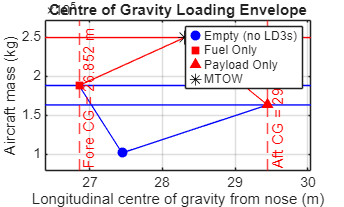

assert(abs(xc(4)-x_CG)<1e-8 && abs(mass(4)-total_mass_kg)<1e-6);

figure('Name','Centre of Gravity Loading Envelope','Color','white');
hold on; grid on; box on;
for k = [2 3]
    quiver(xc(1),mass(1),xc(k)-xc(1),mass(k)-mass(1),0,'b','MaxHeadSize',0.10);
    quiver(xc(k),mass(k),xc(4)-xc(k),mass(4)-mass(k),0,'r','MaxHeadSize',0.10);
end
xline(min(xc),'--r',sprintf('Fore CG = %.3f m',min(xc)),'LabelVerticalAlignment','bottom');
xline(max(xc),'--r',sprintf('Aft CG = %.3f m',max(xc)),'LabelVerticalAlignment','bottom');
h(1) = plot(xc(1),mass(1),'bo','MarkerFaceColor','b');
h(2) = plot(xc(2),mass(2),'rs','MarkerFaceColor','r');
h(3) = plot(xc(3),mass(3),'r^','MarkerFaceColor','r');
h(4) = plot(xc(4),mass(4),'k*','MarkerSize',9);
legend(h,{'Empty (no LD3s)','Fuel Only','Payload Only','MTOW'},'Location','best');
xlabel('Longitudinal centre of gravity from nose (m)'); ylabel('Aircraft mass (kg)');
title('Centre of Gravity Loading Envelope');
dx = max(max(xc)-min(xc),0.1); dy = max(mass)-min(mass);
xlim([min(xc)-0.18*dx,max(xc)+0.23*dx]); ylim([min(mass)-0.15*dy,max(mass)+0.15*dy]);
hold off;


%% LOCAL FUNCTIONS
%% ========================================================================

function TW = cruiseTW(WS, alt_ft, beta, alpha, M, CD0, K, ft2m)
    [~, a, ~, rho] = atmosisa(alt_ft*ft2m);
    q  = 0.5*rho*(M*a)^2;
    TW = (alpha/beta)*((q*CD0./(alpha*WS)) + (alpha*WS/q)*K);
end

function TW = climbTW(WS, alt_ft, roc_fpm, V, beta, alpha, CD0, K, ft2m)
    [~, ~, ~, rho] = atmosisa(alt_ft*ft2m);
    q  = 0.5*rho*V^2;
    gamma_term = (roc_fpm*0.00508)/V;      % ROC [m/s] / V
    TW = (alpha/beta)*(gamma_term + (q*CD0./(alpha*WS)) + (alpha*WS/q)*K);
end


function [area, x_ac] = sizeTail(volumeProduct, x_root, x_wing_ac, AR, taper, sweep, exposedFraction)
    % Span is full HT span or fin height. The centroid is measured on one panel.
    % Both root chord and quarter-chord sweep offset scale with sqrt(area).
    rootArm = x_root - x_wing_ac;
    rootChordFactor = 2/(sqrt(AR)*(1 + taper));
    centroidFactor = exposedFraction*sqrt(AR)*(1 + 2*taper)/(3*(1 + taper));
    acFactor = 0.25*rootChordFactor + centroidFactor*tand(sweep);
    area = fzero(@(S) S*(rootArm + acFactor*sqrt(S)) - volumeProduct, ...
                 [0, volumeProduct/rootArm]);
    x_ac = x_root + acFactor*sqrt(area);
end
function [xForward,xAft] = arrangeLD3(holdStart,holdEnd,boxFront,boxAft,pitch,nRows)
    % Longitudinal row centres [m]. Each row holds two LD3s side by side.
    validateattributes(nRows,{'numeric'},{'scalar','integer','nonnegative','finite'});
    validateattributes(pitch,{'numeric'},{'scalar','positive','finite'});
    assert(all(isfinite([holdStart holdEnd boxFront boxAft])) && ...
        holdEnd > holdStart && boxAft > boxFront, 'Invalid hold or wing-box limits.');
    forwardEnd = min(max(boxFront,holdStart),holdEnd);
    aftStart   = min(max(boxAft,holdStart),holdEnd);
    tol = 16*eps(max([1 abs(holdStart) abs(holdEnd)]));
    capForward = floor((forwardEnd-holdStart+tol)/pitch);
    capAft = floor((holdEnd-aftStart+tol)/pitch);
    if capForward + capAft < nRows
        error('LD3:InsufficientSpace', ...
            '%d lower rows required; only %d forward and %d aft fit.',nRows,capForward,capAft);
    end
    % Fill forward first. Centre the occupied block in each usable bay.
    nf = min(capForward,nRows);
    na = nRows-nf;
    xForward = (holdStart+forwardEnd)/2 + ((1:nf)-(nf+1)/2)*pitch;
    xAft = (aftStart+holdEnd)/2 + ((1:na)-(na+1)/2)*pitch;
end
